%%Question1

clear all; close all; clc;
%%%%% OFDM parameters %%%%%
params.del_f = 1e4;              % subcarrier spacing = 10kHz
params.numCarriers = 512;        % fft size = 512
params.prefixDuration = 6.25e-6; % CP duration =6.25 mus

params.sampleRate = params.del_f * params.numCarriers;
params.prefixLength = round(params.prefixDuration * params.sampleRate);
params.blockDuration = (params.numCarriers + params.prefixLength) / params.sampleRate;
params.preamblePeriodicity = 5;               % Frame size = 5
params.lowerGuardTones = -255:-241;
params.upperGuardTones = 241:256;
params.guardTones = [params.lowerGuardTones params.upperGuardTones];   % Guard bands
params.DCSubcarrier = [0];                   % DC carrier
params.pilots = true;
params.pilotPeriodicity = 8;

%%%% Channel Parameters %%%%%
params.pathGains = [-3 0 -1 -4 -9 -17];
params.delays = [0 7 13 18 21 26];
% Taps = 16;
% params.delays = 1:Taps;
% params.pathGains = zeros([1 Taps]);

% params.CFO = 28.65e3;                      % Maximum offset = 28.65kHz
params.CFO = 0;                      % Maximum offset = 28.65kHz
params.SNR = 10;

%%%%% Modulation parameters %%%%%
params.modulationType = 'QAM';
params.modulationOrder = 4;
params.numFrames = 1;

%%%%% Channel estimation %%%%%
% params.estimationType = "ZF";
% params.estimationType = "ZF_LINEAR_INTERPOLATE";
params.estimationType = "ZF_FFT_INTERPOLATE";

%%%%% Simulation %%%%%
S = OFDM.generateOFDMframe(params);
s = OFDM.modulate(S, params);
[r, h] = OFDM.channel(s, params);
% r = s;
R = OFDM.demodulate(r, params);

hest = OFDM.channelEstimate(R, params)

ans = 0

ans = 0

ans = 0

ans = 0

hest =    0.1691 + 0.0400i   0.1858 + 0.0301i   0.1858 + 0.0391i   0.1924 + 0.0436i
   0.1432 + 0.0944i   0.1607 + 0.0898i   0.1566 + 0.0997i   0.1612 + 0.1066i
   0.0961 + 0.1298i   0.1125 + 0.1300i   0.1041 + 0.1385i   0.1054 + 0.1461i
   0.0409 + 0.1386i   0.0548 + 0.1422i   0.0432 + 0.1476i   0.0415 + 0.1537i
  -0.0075 + 0.1216i   0.0033 + 0.1270i  -0.0096 + 0.1285i  -0.0127 + 0.1315i
  -0.0377 + 0.0876i  -0.0296 + 0.0933i  -0.0422 + 0.0911i  -0.0443 + 0.0911i
  -0.0454 + 0.0495i  -0.0390 + 0.0546i  -0.0504 + 0.0498i  -0.0497 + 0.0481i
  -0.0341 + 0.0197i  -0.0283 + 0.0240i  -0.0386 + 0.0175i  -0.0347 + 0.0163i
  -0.0135 + 0.0056i  -0.0073 + 0.0096i  -0.0169 + 0.0017i  -0.0108 + 0.0031i
   0.0057 + 0.0074i   0.0124 + 0.0122i   0.0031 + 0.0023i   0.0094 + 0.0071i
   0.0150 + 0.0192i   0.0219 + 0.0257i   0.0133 + 0.0127i   0.0179 + 0.0205i
   0.0121 + 0.0320i   0.0181 + 0.0408i   0.0118 + 0.0241i   0.0133 + 0.0332i
   0.0002 + 0.0382i   0.0041 + 0.0490i   0.0024 + 0.0290i   0.0009 + 

mse = OFDM.channelMSE(h, hest,params)

mse = 0.0292

mse_db = 10*log10(mse)

mse_db = -15.3412

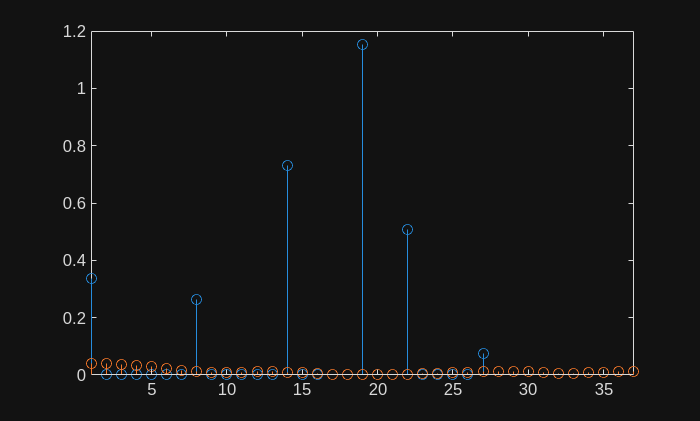


figure;
stem(abs(h))
hold on;
stem(abs(hest(:,1)))
xlim([1 params.prefixLength+5])